Chiudo tutto e carico il Dataset

% clear
% close all
    
training_data = [];
training_labels = [];
test_data = [];
test_labels = [];
for i = 1:6
    if i == 6
        filename = "cifar-10-batches-mat/test_batch.mat"
        load(filename)
        test_data = data;
        test_labels = labels;
    else
        filename = "cifar-10-batches-mat/data_batch_" + i + ".mat"
        load(filename)
        training_data = [training_data; data];
        training_labels = [training_labels; labels];
    end
end

filename = "cifar-10-batches-mat/data_batch_1.mat"

filename = "cifar-10-batches-mat/data_batch_2.mat"

filename = "cifar-10-batches-mat/data_batch_3.mat"

filename = "cifar-10-batches-mat/data_batch_4.mat"

filename = "cifar-10-batches-mat/data_batch_5.mat"

filename = "cifar-10-batches-mat/test_batch.mat"


clear data
clear labels
clear i
clear filename

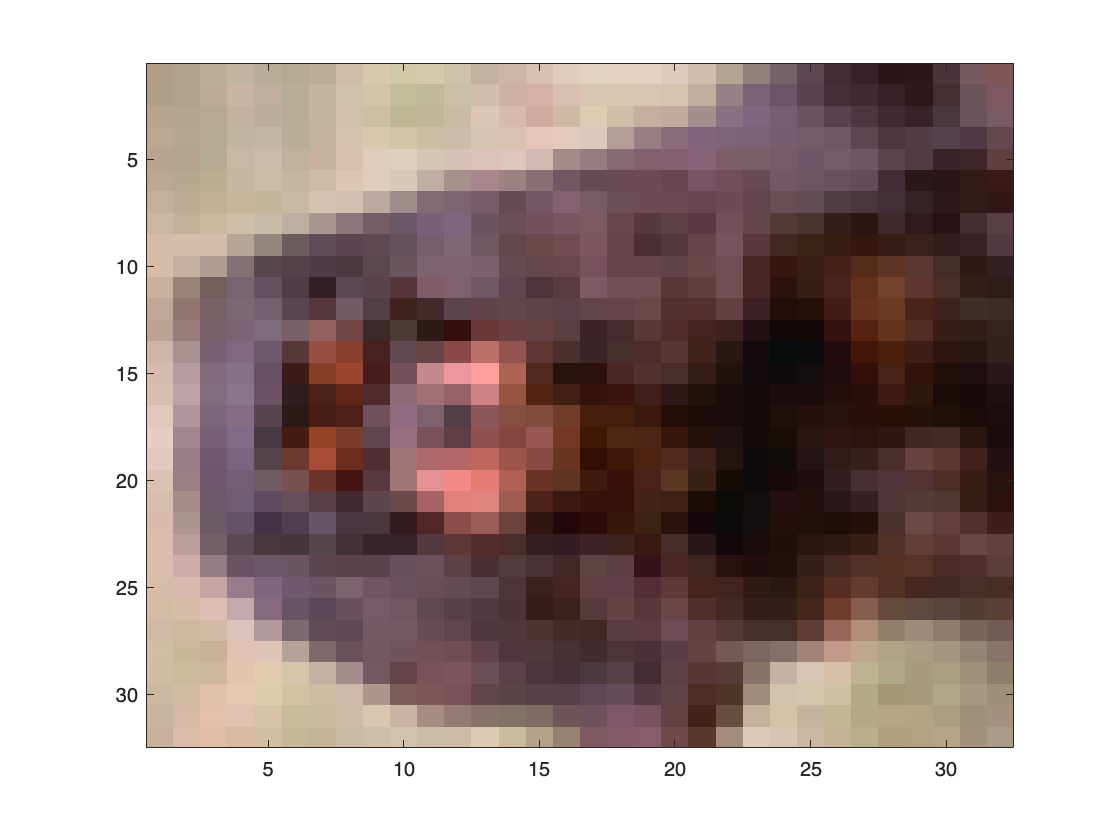

figure(1)
    imagesc(reshape(training_data(20000, :), [32,32,3]));

dataset_totale = double([training_data; test_data]);
test_data = double(test_data);
test_labels = double(test_labels);
training_data = double(training_data);
training_labels = double(training_labels);

Devo trasporre per ottenere la giusta dimensione di U e Z, dove ricordiamo U essere la matrice degli scores, e che quindi deve mantenere un numero di righe pari a quello iniziale ed un numero di colonne pari alle componenti scelte di preservare con la pca. Al contrario i loading devono contenere un numero di righe pari alle colonne iniziali (perche' ci dice quanto ogni pixel e' influente) per il numero di componenti scelte.

[U, Z] = pca(dataset_totale', 'NumComponents',2);

Andiamo a vedere come sono distribuite le classi per training e test set scomponendo il dataset con la pca a 2 componenti per puri scopi visualizzativi.

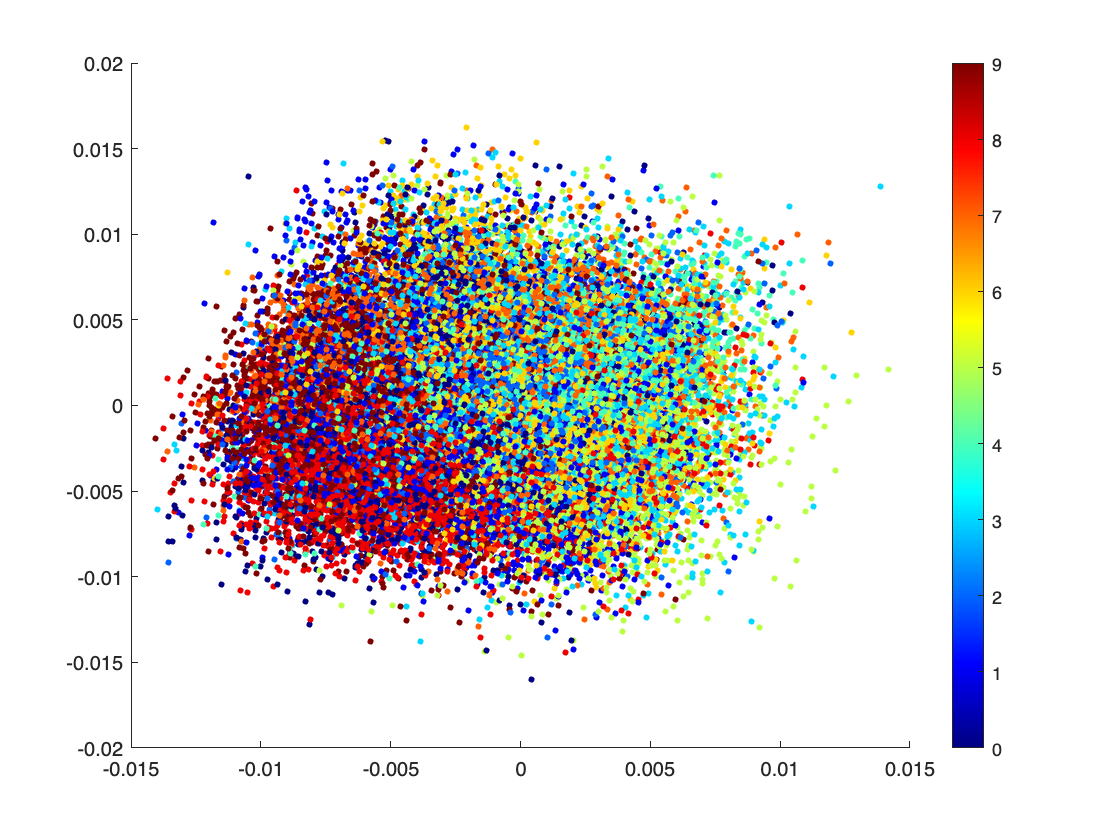

figure(1)
    scatter(U(1:50000,1), U(1:50000,2), 10, training_labels, 'filled')
    colormap(jet)
    colorbar

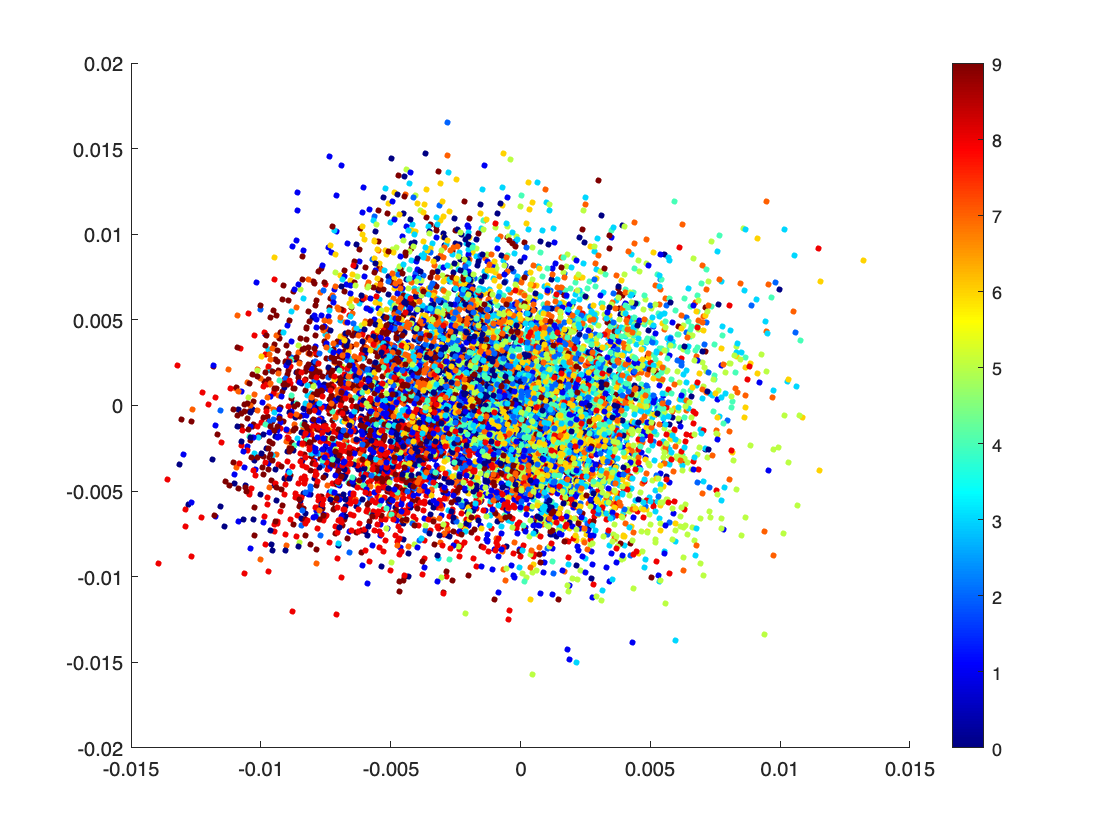

figure(2)
    scatter(U(50001:60000,1), U(50001:60000,2), 10, test_labels, 'filled')
    colormap(jet)
    colorbar

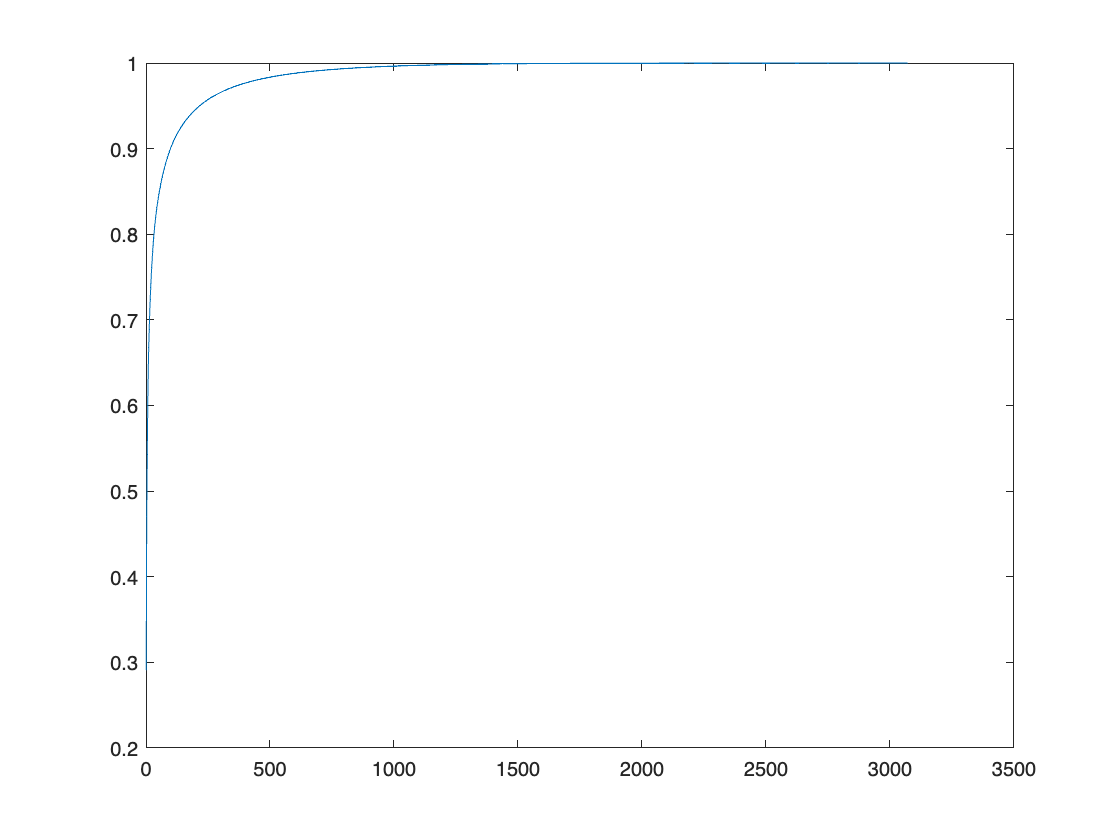

C = cov(dataset_totale);
E = eig(C);
E = sort(E, 'descend');
tot = sum(E);
cum = cumsum(E); % ci fa la somma cumulata: la somma del primo, somma del primo + secondo, primo + secondo + terzo, ecc..
cum_norm = cum/tot;
figure(5);
plot(cum_norm);

FACCIO PCA CON 658 COMPONENTI PER PRESERVARE 99.0% INFORMAZIONE

[U_658, Z_658] = pca(dataset_totale', "NumComponents", 658);

tree_658 = fitctree(U_658(1:50000, :), training_labels)

tree_658 =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
          NumObservations: 50000


  Properties, Methods


tree_predictions_658 = predict(tree_658, U_658(50001:60000, :));
acc = (length(test_labels) - nnz(test_labels-tree_predictions_658)) / (length(test_labels))

acc = 0.2586

% 95% INFO
[U_217, Z_217] = pca(dataset_totale', "NumComponents", 217);
tree_217 = fitctree(U_217(1:50000, :), training_labels)

tree_217 =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
          NumObservations: 50000


  Properties, Methods


tree_predictions_217 = predict(tree_217, U_217(50001:60000, :));
acc = (length(test_labels) - nnz(test_labels-tree_predictions_217)) / (length(test_labels))

acc = 0.2743

80% informazione

[U_33, Z_33] = pca(dataset_totale', "NumComponents", 33);
tree_33 = fitctree(U_33(1:50000, :), training_labels)

tree_33 =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
          NumObservations: 50000


  Properties, Methods


tree_predictions_33 = predict(tree_33, U_33(50001:60000, :));
acc = (length(test_labels) - nnz(test_labels-tree_predictions_33)) / (length(test_labels))

acc = 0.2920

corrette = 0;
for i = 1 : 10000
    if test_labels(i) == tree_predictions_33(i)
%         "Real:" + test_labels(i) + " | " + tree_predictions_33(i) + " :Predicted"
        corrette = corrette + 1;
    end
end

disp("Corrette: " + corrette);

Corrette: 2920


disp("Sbagliate: " + (10000 - corrette));

Sbagliate: 7080


disp("Accuracy: " + (corrette/10000*100) + "%");

Accuracy: 29.2%


training set completo

tree_tot = fitctree(double(training_data), training_labels)

tree_tot =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
          NumObservations: 50000


  Properties, Methods


tree_predictions_tot = predict(tree_tot, double(test_data));
acc = (length(test_labels) - nnz(test_labels-tree_predictions_tot)) / (length(test_labels))

acc = 0.2683

90% informazione

[U_99, Z_99] = pca(dataset_totale', "NumComponents", 99);
tree_99 = fitctree(U_99(1:50000, :), training_labels)

tree_99 =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
          NumObservations: 50000


  Properties, Methods


tree_predictions_99 = predict(tree_99, U_99(50001:60000, :));
acc = (length(test_labels) - nnz(test_labels-tree_predictions_99)) / (length(test_labels))

acc = 0.2802

85% informazione

[U_55, Z_55] = pca(dataset_totale', "NumComponents", 55);
tree_55 = fitctree(U_55(1:50000, :), training_labels)

tree_55 =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
          NumObservations: 50000


  Properties, Methods


tree_predictions_55 = predict(tree_55, U_55(50001:60000, :));
acc = (length(test_labels) - nnz(test_labels-tree_predictions_55)) / (length(test_labels))

acc = 0.2890

LOGISTIC REGRESSION: LASSO E RIDGE

tl_full = templateLinear("Learner","logistic", "Regularization","lasso");
Mdl_lasso_cv_full = fitcecoc(double(training_data), training_labels, "Learners", tl_full, 'coding', 'onevsall', 'CrossVal', 'on', 'KFold', 5)

Mdl_lasso_cv_full =   ClassificationPartitionedLinearECOC
    CrossValidatedModel: 'LinearECOC'
           ResponseName: 'Y'
        NumObservations: 50000
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1 2 3 4 5 6 7 8 9]
         ScoreTransform: 'none'


  Properties, Methods


beta_lasso_full = Mdl_lasso_cv_full.Trained{1}.BinaryLearners{1}.Beta;
bias_lasso_full = Mdl_lasso_cv_full.Trained{1}.BinaryLearners{1}.Bias;
lambda_lasso_full = Mdl_lasso_cv_full.Trained{1}.BinaryLearners{1}.Lambda;

tl_lasso_full = templateLinear('Learner', 'logistic', 'Regularization', 'lasso',...
    'Beta', beta_lasso_full, 'Bias', bias_lasso_full, 'Lambda', lambda_lasso_full);
Mdl_lasso_full = fitcecoc(double(training_data), training_labels, 'Learners', tl_lasso_full, 'coding', 'onevsall');

prediction_full = predict(Mdl_lasso_full, double(test_data));
acc = (length(test_labels) - nnz(test_labels-prediction_full)) / (length(test_labels))

acc = 0.3027

% Mdl = fitcecoc(double(training_data), training_labels, "Learners", tl, 'coding', 'onevsall')

% labels = predict(Mdl,double(test_data));
% idx = randsample(sum(900:910),10);
% table(test_labels(idx),labels(idx),...
%     'VariableNames',{'TrueLabels','PredictedLabels'})
% acc = (length(test_labels) - nnz(test_labels-labels)) / (length(test_labels))

% RIDGE
tl_full_r = templateLinear("Learner","logistic", "Regularization","ridge");
Mdl_ridge_cv_full = fitcecoc(double(training_data), training_labels, "Learners", tl_full_r, 'coding', 'onevsall', 'CrossVal', 'on', 'KFold', 5)

Mdl_ridge_cv_full =   ClassificationPartitionedLinearECOC
    CrossValidatedModel: 'LinearECOC'
           ResponseName: 'Y'
        NumObservations: 50000
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1 2 3 4 5 6 7 8 9]
         ScoreTransform: 'none'


  Properties, Methods


beta_ridge_full = Mdl_ridge_cv_full.Trained{1}.BinaryLearners{1}.Beta;
bias_ridge_full = Mdl_ridge_cv_full.Trained{1}.BinaryLearners{1}.Bias;
lambda_ridge_full = Mdl_ridge_cv_full.Trained{1}.BinaryLearners{1}.Lambda;

tl_ridge_full = templateLinear('Learner', 'logistic', 'Regularization', 'ridge',...
    'Beta', beta_ridge_full, 'Bias', bias_ridge_full, 'Lambda', lambda_ridge_full);
Mdl_ridge_full = fitcecoc(double(training_data), training_labels, 'Learners', tl_ridge_full, 'coding', 'onevsall');

prediction_full = predict(Mdl_ridge_full, double(test_data));
acc = (length(test_labels) - nnz(test_labels-prediction_full)) / (length(test_labels))

acc = 0.2574

Lasso con PCA 33 comp.

tl = templateLinear("Learner","logistic", "Regularization","lasso");
Mdl_lasso_cv = fitcecoc(U_33(1:50000, :), double(training_labels), "Learners", tl, 'coding', 'onevsall', 'CrossVal', 'on', 'KFold', 5)

Mdl_lasso_cv =   ClassificationPartitionedLinearECOC
    CrossValidatedModel: 'LinearECOC'
           ResponseName: 'Y'
        NumObservations: 50000
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1 2 3 4 5 6 7 8 9]
         ScoreTransform: 'none'


  Properties, Methods


beta_lasso = Mdl_lasso_cv.Trained{1}.BinaryLearners{1}.Beta;
bias_lasso = Mdl_lasso_cv.Trained{1}.BinaryLearners{1}.Bias;
lambda_lasso = Mdl_lasso_cv.Trained{1}.BinaryLearners{1}.Lambda;

tl_lasso = templateLinear('Learner', 'logistic', 'Regularization', 'lasso',...
    'Beta', beta_lasso, 'Bias', bias_lasso, 'Lambda', lambda_lasso);
Mdl_lasso = fitcecoc(U_33(1:50000, :), training_labels, 'Learners', tl_lasso, 'coding', 'onevsall');

prediction = predict(Mdl_lasso, U_33(50001:60000, :));
prediction = double(prediction);
test_labels = double(test_labels);
acc = (length(test_labels) - nnz(test_labels-prediction)) / (length(test_labels))

acc = 0.3439

idx = kmeans(dataset_totale, 10);

test_labels = double(test_labels);
acc = (length(test_labels) - nnz(test_labels-idx(50001:60000))) / (length(test_labels))

acc = 0.0751

corrette = 0;
for i = 1 : 10000
    if test_labels(i) == idx(50000+i)
%     "Real:" + test_labels(i) + " | " + idx(50000+i) + " :Predicted"
        corrette = corrette + 1;
    end
end

disp("Corrette: " + corrette);

Corrette: 751


disp("Sbagliate: " + (10000 - corrette));

Sbagliate: 9249


disp("Accuracy: " + (corrette/10000*100) + "%");

Accuracy: 7.51%


tl_r = templateLinear("Learner","logistic", "Regularization","ridge");
% devo usare il training set.
Mdl_ridge_cv = fitcecoc(U_33(1:50000, :), training_labels, "Learners", tl_r, 'coding', 'onevsall', 'CrossVal', 'on', 'KFold', 5)

Mdl_ridge_cv =   ClassificationPartitionedLinearECOC
    CrossValidatedModel: 'LinearECOC'
           ResponseName: 'Y'
        NumObservations: 50000
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1 2 3 4 5 6 7 8 9]
         ScoreTransform: 'none'


  Properties, Methods


beta_ridge = Mdl_ridge_cv.Trained{1}.BinaryLearners{1}.Beta;
bias_ridge = Mdl_ridge_cv.Trained{1}.BinaryLearners{1}.Bias;
lambda_ridge = Mdl_ridge_cv.Trained{1}.BinaryLearners{1}.Lambda;

tl_ridge = templateLinear('Learner', 'logistic', 'Regularization', 'ridge',...
    'Beta', beta_ridge, 'Bias', bias_ridge, 'Lambda', lambda_ridge);
Mdl_ridge = fitcecoc(U_33(1:50000, :), training_labels, 'Learners', tl_ridge, 'coding', 'onevsall');
prediction = predict(Mdl_ridge, U_33(50001:60000, :));
acc = (length(test_labels) - nnz(test_labels-prediction)) / (length(test_labels))

acc = 0.3495

% LASSO % CV % 55 comp: 85% INFO
tl = templateLinear("Learner","logistic", "Regularization","lasso");
Mdl_lasso_cv = fitcecoc(U_55(1:50000, :), double(training_labels), "Learners", tl, 'coding', 'onevsall', 'CrossVal', 'on', 'KFold', 5)

Mdl_lasso_cv =   ClassificationPartitionedLinearECOC
    CrossValidatedModel: 'LinearECOC'
           ResponseName: 'Y'
        NumObservations: 50000
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1 2 3 4 5 6 7 8 9]
         ScoreTransform: 'none'


  Properties, Methods


beta_lasso = Mdl_lasso_cv.Trained{1}.BinaryLearners{1}.Beta;
bias_lasso = Mdl_lasso_cv.Trained{1}.BinaryLearners{1}.Bias;
lambda_lasso = Mdl_lasso_cv.Trained{1}.BinaryLearners{1}.Lambda;
tl_lasso = templateLinear('Learner', 'logistic', 'Regularization', 'lasso',...
    'Beta', beta_lasso, 'Bias', bias_lasso, 'Lambda', lambda_lasso);
Mdl_lasso = fitcecoc(U_55(1:50000, :), training_labels, 'Learners', tl_lasso, 'coding', 'onevsall');

prediction = predict(Mdl_lasso, U_55(50001:60000, :));
acc = (length(test_labels) - nnz(test_labels-prediction)) / (length(test_labels))

acc = 0.3491


% RIDGE % CV
tl_r = templateLinear("Learner","logistic", "Regularization","ridge");
Mdl_ridge_cv = fitcecoc(U_55(1:50000, :), training_labels, "Learners", tl_r, 'coding', 'onevsall', 'CrossVal', 'on', 'KFold', 5)

Mdl_ridge_cv =   ClassificationPartitionedLinearECOC
    CrossValidatedModel: 'LinearECOC'
           ResponseName: 'Y'
        NumObservations: 50000
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1 2 3 4 5 6 7 8 9]
         ScoreTransform: 'none'


  Properties, Methods


beta_ridge = Mdl_ridge_cv.Trained{1}.BinaryLearners{1}.Beta;
bias_ridge = Mdl_ridge_cv.Trained{1}.BinaryLearners{1}.Bias;
lambda_ridge = Mdl_ridge_cv.Trained{1}.BinaryLearners{1}.Lambda;
tl_ridge = templateLinear('Learner', 'logistic', 'Regularization', 'ridge',...
    'Beta', beta_ridge, 'Bias', bias_ridge, 'Lambda', lambda_ridge);
Mdl_ridge = fitcecoc(U_55(1:50000, :), training_labels, 'Learners', tl_ridge, 'coding', 'onevsall');

prediction = predict(Mdl_ridge, U_55(50001:60000, :));
acc = (length(test_labels) - nnz(test_labels-prediction)) / (length(test_labels))

acc = 0.3614

% LASSO % CV % 99 comp: 90% INFO
tl = templateLinear("Learner","logistic", "Regularization","lasso");
Mdl_lasso_cv = fitcecoc(U_99(1:50000, :), double(training_labels), "Learners", tl, 'coding', 'onevsall', 'CrossVal', 'on', 'KFold', 5)

Mdl_lasso_cv =   ClassificationPartitionedLinearECOC
    CrossValidatedModel: 'LinearECOC'
           ResponseName: 'Y'
        NumObservations: 50000
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1 2 3 4 5 6 7 8 9]
         ScoreTransform: 'none'


  Properties, Methods


beta_lasso = Mdl_lasso_cv.Trained{1}.BinaryLearners{1}.Beta;
bias_lasso = Mdl_lasso_cv.Trained{1}.BinaryLearners{1}.Bias;
lambda_lasso = Mdl_lasso_cv.Trained{1}.BinaryLearners{1}.Lambda;
tl_lasso = templateLinear('Learner', 'logistic', 'Regularization', 'lasso',...
    'Beta', beta_lasso, 'Bias', bias_lasso, 'Lambda', lambda_lasso);
Mdl_lasso = fitcecoc(U_99(1:50000, :), training_labels, 'Learners', tl_lasso, 'coding', 'onevsall');

prediction = predict(Mdl_lasso, U_99(50001:60000, :));
acc = (length(test_labels) - nnz(test_labels-prediction)) / (length(test_labels))

acc = 0.3619


% RIDGE % CV
tl_r = templateLinear("Learner","logistic", "Regularization","ridge");
Mdl_ridge_cv = fitcecoc(U_99(1:50000, :), training_labels, "Learners", tl_r, 'coding', 'onevsall', 'CrossVal', 'on', 'KFold', 5)

Mdl_ridge_cv =   ClassificationPartitionedLinearECOC
    CrossValidatedModel: 'LinearECOC'
           ResponseName: 'Y'
        NumObservations: 50000
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1 2 3 4 5 6 7 8 9]
         ScoreTransform: 'none'


  Properties, Methods


beta_ridge = Mdl_ridge_cv.Trained{1}.BinaryLearners{1}.Beta;
bias_ridge = Mdl_ridge_cv.Trained{1}.BinaryLearners{1}.Bias;
lambda_ridge = Mdl_ridge_cv.Trained{1}.BinaryLearners{1}.Lambda;
tl_ridge = templateLinear('Learner', 'logistic', 'Regularization', 'ridge',...
    'Beta', beta_ridge, 'Bias', bias_ridge, 'Lambda', lambda_ridge);
Mdl_ridge = fitcecoc(U_99(1:50000, :), training_labels, 'Learners', tl_ridge, 'coding', 'onevsall');

prediction = predict(Mdl_ridge, U_99(50001:60000, :));
acc = (length(test_labels) - nnz(test_labels-prediction)) / (length(test_labels))

acc = 0.3837

% LASSO % CV % 217 comp: 95% INFO
tl = templateLinear("Learner","logistic", "Regularization","lasso");
Mdl_lasso_cv = fitcecoc(U_217(1:50000, :), double(training_labels), "Learners", tl, 'coding', 'onevsall', 'CrossVal', 'on', 'KFold', 5)

Mdl_lasso_cv =   ClassificationPartitionedLinearECOC
    CrossValidatedModel: 'LinearECOC'
           ResponseName: 'Y'
        NumObservations: 50000
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1 2 3 4 5 6 7 8 9]
         ScoreTransform: 'none'


  Properties, Methods


beta_lasso = Mdl_lasso_cv.Trained{1}.BinaryLearners{1}.Beta;
bias_lasso = Mdl_lasso_cv.Trained{1}.BinaryLearners{1}.Bias;
lambda_lasso = Mdl_lasso_cv.Trained{1}.BinaryLearners{1}.Lambda;
tl_lasso = templateLinear('Learner', 'logistic', 'Regularization', 'lasso',...
    'Beta', beta_lasso, 'Bias', bias_lasso, 'Lambda', lambda_lasso);
Mdl_lasso = fitcecoc(U_217(1:50000, :), training_labels, 'Learners', tl_lasso, 'coding', 'onevsall');

prediction = predict(Mdl_lasso, U_217(50001:60000, :));
acc = (length(test_labels) - nnz(test_labels-prediction)) / (length(test_labels))

acc = 0.1000


% RIDGE % CV
tl_r = templateLinear("Learner","logistic", "Regularization","ridge");
Mdl_ridge_cv = fitcecoc(U_217(1:50000, :), training_labels, "Learners", tl_r, 'coding', 'onevsall', 'CrossVal', 'on', 'KFold', 5)

Mdl_ridge_cv =   ClassificationPartitionedLinearECOC
    CrossValidatedModel: 'LinearECOC'
           ResponseName: 'Y'
        NumObservations: 50000
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1 2 3 4 5 6 7 8 9]
         ScoreTransform: 'none'


  Properties, Methods


beta_ridge = Mdl_ridge_cv.Trained{1}.BinaryLearners{1}.Beta;
bias_ridge = Mdl_ridge_cv.Trained{1}.BinaryLearners{1}.Bias;
lambda_ridge = Mdl_ridge_cv.Trained{1}.BinaryLearners{1}.Lambda;
tl_ridge = templateLinear('Learner', 'logistic', 'Regularization', 'ridge',...
    'Beta', beta_ridge, 'Bias', bias_ridge, 'Lambda', lambda_ridge);
Mdl_ridge = fitcecoc(U_217(1:50000, :), training_labels, 'Learners', tl_ridge, 'coding', 'onevsall');

prediction = predict(Mdl_ridge, U_217(50001:60000, :));
acc = (length(test_labels) - nnz(test_labels-prediction)) / (length(test_labels))

acc = 0.1000

% LASSO % CV % 658 comp: 99% INFO
tl = templateLinear("Learner","logistic", "Regularization","lasso");
Mdl_lasso_cv = fitcecoc(U_658(1:50000, :), double(training_labels), "Learners", tl, 'coding', 'onevsall', 'CrossVal', 'on', 'KFold', 5)

Mdl_lasso_cv =   ClassificationPartitionedLinearECOC
    CrossValidatedModel: 'LinearECOC'
           ResponseName: 'Y'
        NumObservations: 50000
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1 2 3 4 5 6 7 8 9]
         ScoreTransform: 'none'


  Properties, Methods


beta_lasso = Mdl_lasso_cv.Trained{1}.BinaryLearners{1}.Beta;
bias_lasso = Mdl_lasso_cv.Trained{1}.BinaryLearners{1}.Bias;
lambda_lasso = Mdl_lasso_cv.Trained{1}.BinaryLearners{1}.Lambda;
tl_lasso = templateLinear('Learner', 'logistic', 'Regularization', 'lasso',...
    'Beta', beta_lasso, 'Bias', bias_lasso, 'Lambda', lambda_lasso);
Mdl_lasso = fitcecoc(U_658(1:50000, :), training_labels, 'Learners', tl_lasso, 'coding', 'onevsall');

prediction = predict(Mdl_lasso, U_658(50001:60000, :));
acc = (length(test_labels) - nnz(test_labels-prediction)) / (length(test_labels))

acc = 0.1000


% RIDGE % CV
tl_r = templateLinear("Learner","logistic", "Regularization","ridge");
Mdl_ridge_cv = fitcecoc(U_658(1:50000, :), training_labels, "Learners", tl_r, 'coding', 'onevsall', 'CrossVal', 'on', 'KFold', 5)

Mdl_ridge_cv =   ClassificationPartitionedLinearECOC
    CrossValidatedModel: 'LinearECOC'
           ResponseName: 'Y'
        NumObservations: 50000
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1 2 3 4 5 6 7 8 9]
         ScoreTransform: 'none'


  Properties, Methods


beta_ridge = Mdl_ridge_cv.Trained{1}.BinaryLearners{1}.Beta;
bias_ridge = Mdl_ridge_cv.Trained{1}.BinaryLearners{1}.Bias;
lambda_ridge = Mdl_ridge_cv.Trained{1}.BinaryLearners{1}.Lambda;
tl_ridge = templateLinear('Learner', 'logistic', 'Regularization', 'ridge',...
    'Beta', beta_ridge, 'Bias', bias_ridge, 'Lambda', lambda_ridge);
Mdl_ridge = fitcecoc(U_658(1:50000, :), training_labels, 'Learners', tl_ridge, 'coding', 'onevsall');

prediction = predict(Mdl_ridge, U_658(50001:60000, :));
acc = (length(test_labels) - nnz(test_labels-prediction)) / (length(test_labels))

acc = 0.1000